This system is related to "Eulerian wobble", or the "tennis racket theorem."


$$\frac{du}{dt} = vw \\
\frac{dv}{dt} = -2uw  \qquad u(0),v(0),w(0)\; \text{random}\\
\frac{dw}{dt} = uv$$


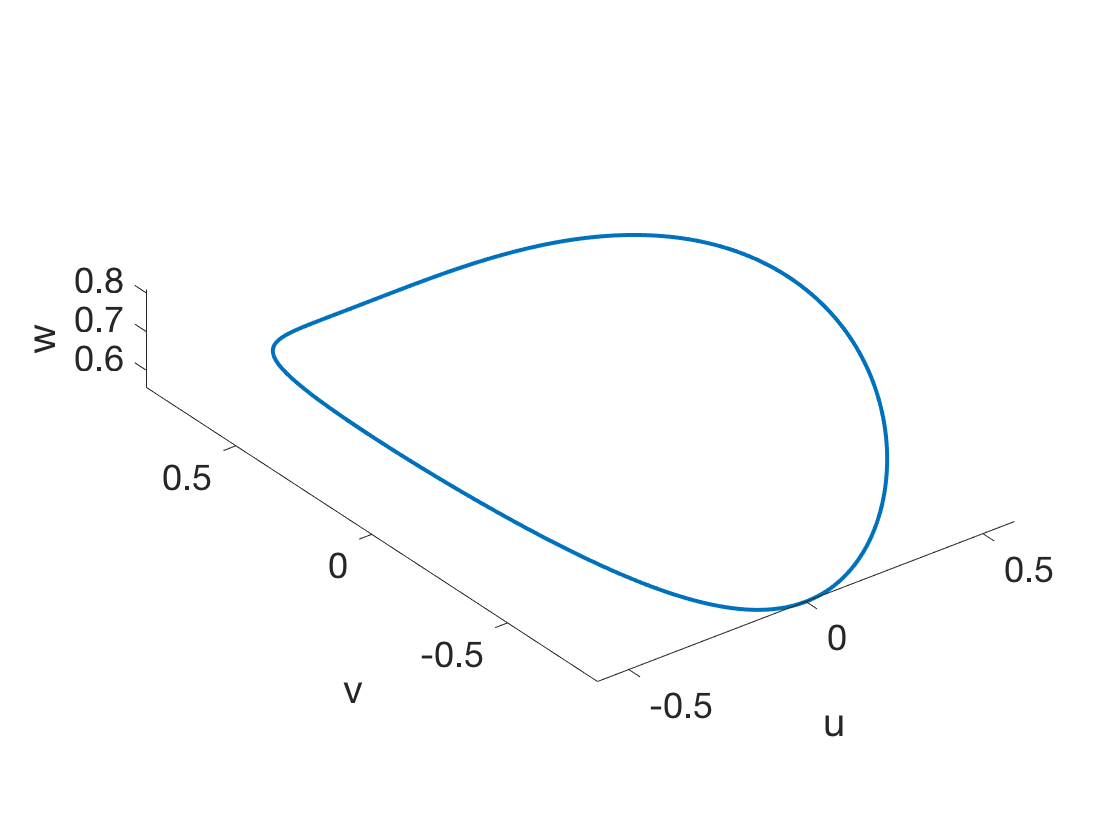

N = chebop(0,12);
N.op = @(t,u,v,w) [ diff(u)-v*w; 
                    diff(v) + 2*u*w; 
                    diff(w)-u*v         ]; 
x = randn(3,1);  N.lbc = x/norm(x);  
[u,v,w] = N\0;
clf, plot3(u,v,w)
axis equal
xlabel u, ylabel v, zlabel w

By itself the solution doesn't look like much. But if we repeat many times, a striking feature emerges.

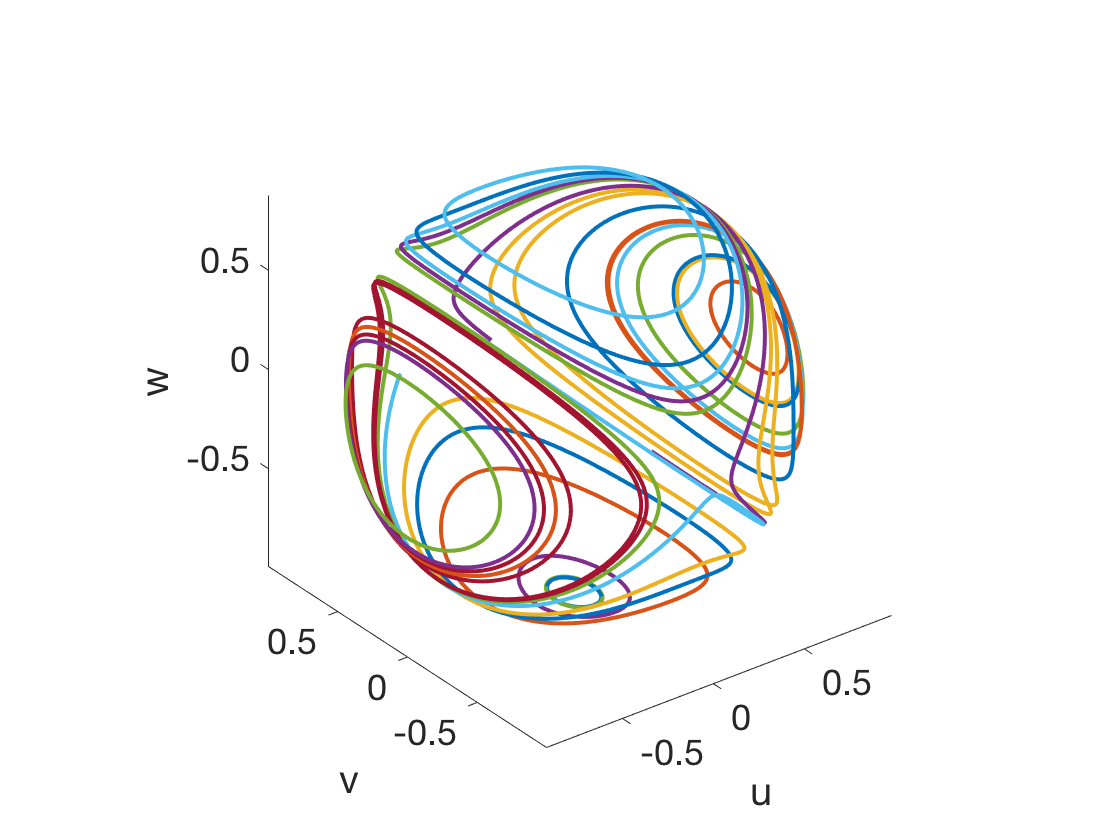

for k = 1:30
    x = randn(3,1);  N.lbc = x/norm(x);  
    [u,v,w] = N\0;
    hold on, plot3(u,v,w)
end

It seems like the solutions all lie on a sphere. Here is one way to verify that property.

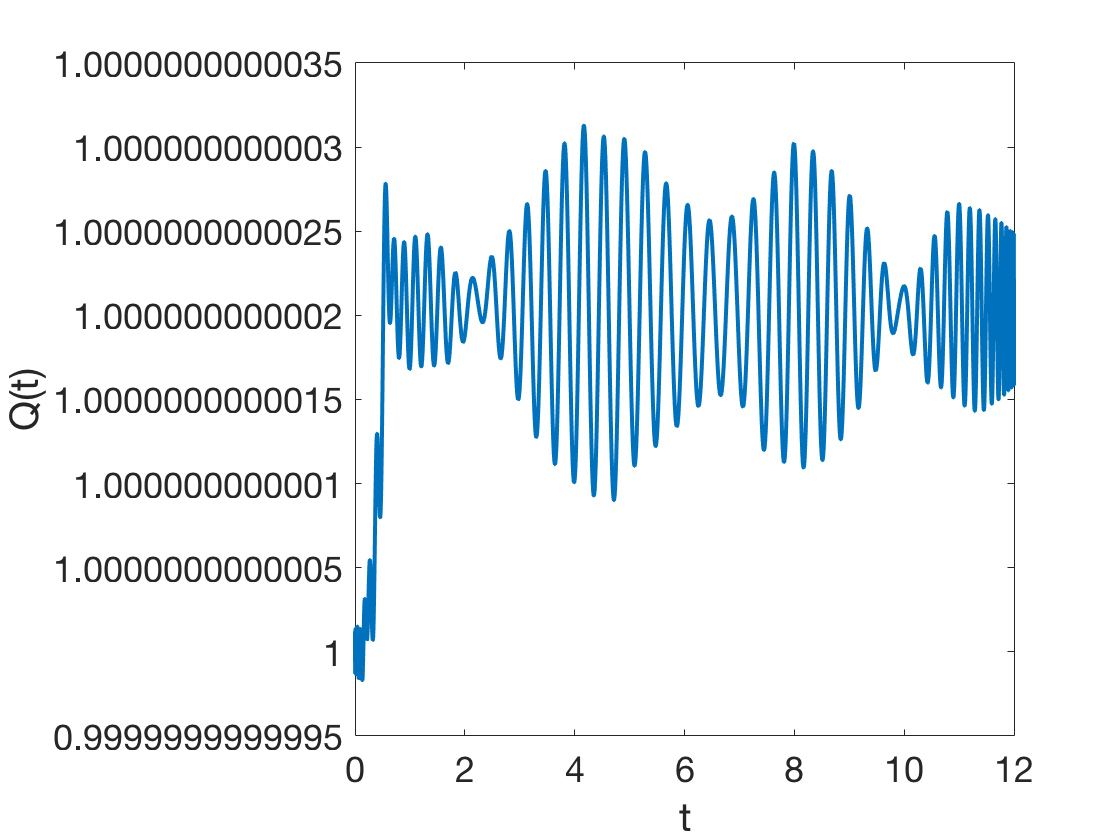

Q = u^2+v^2+w^2;
clf, plot(Q)
xlabel t, ylabel Q(t)

Here's another way. This one happens to lead to a quick way to show the property analytically. 

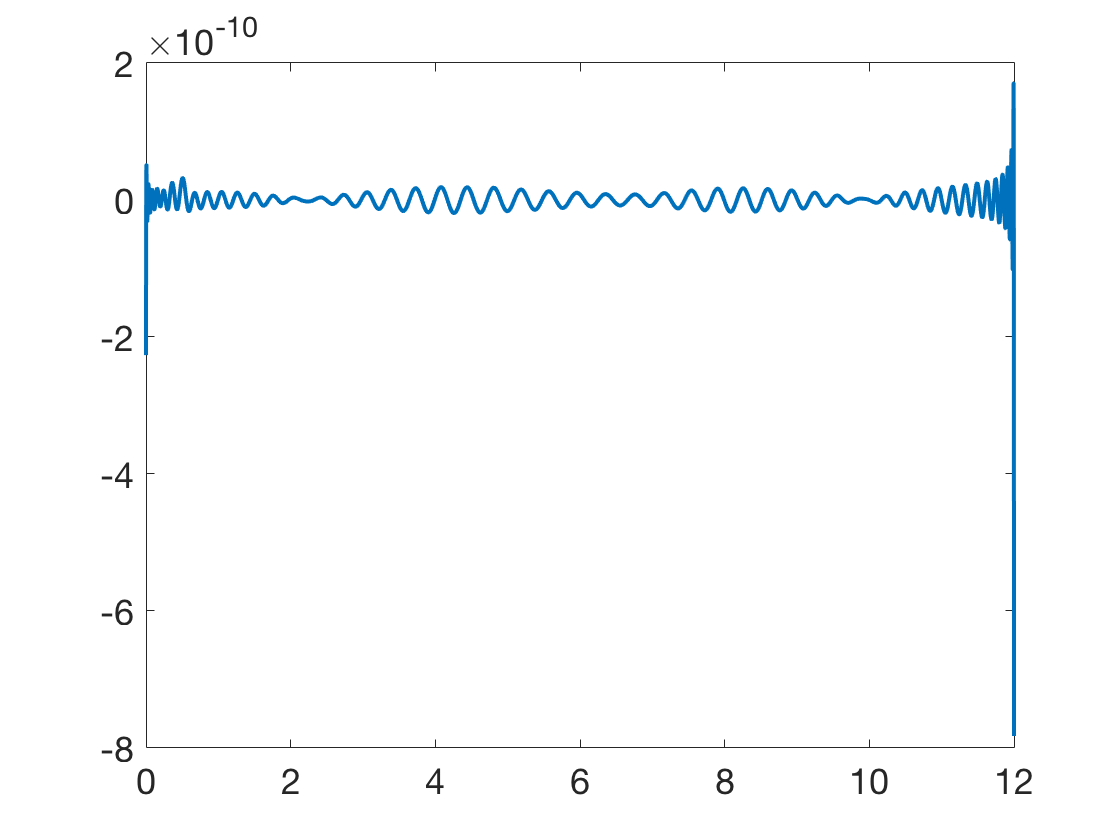

plot(diff(Q))